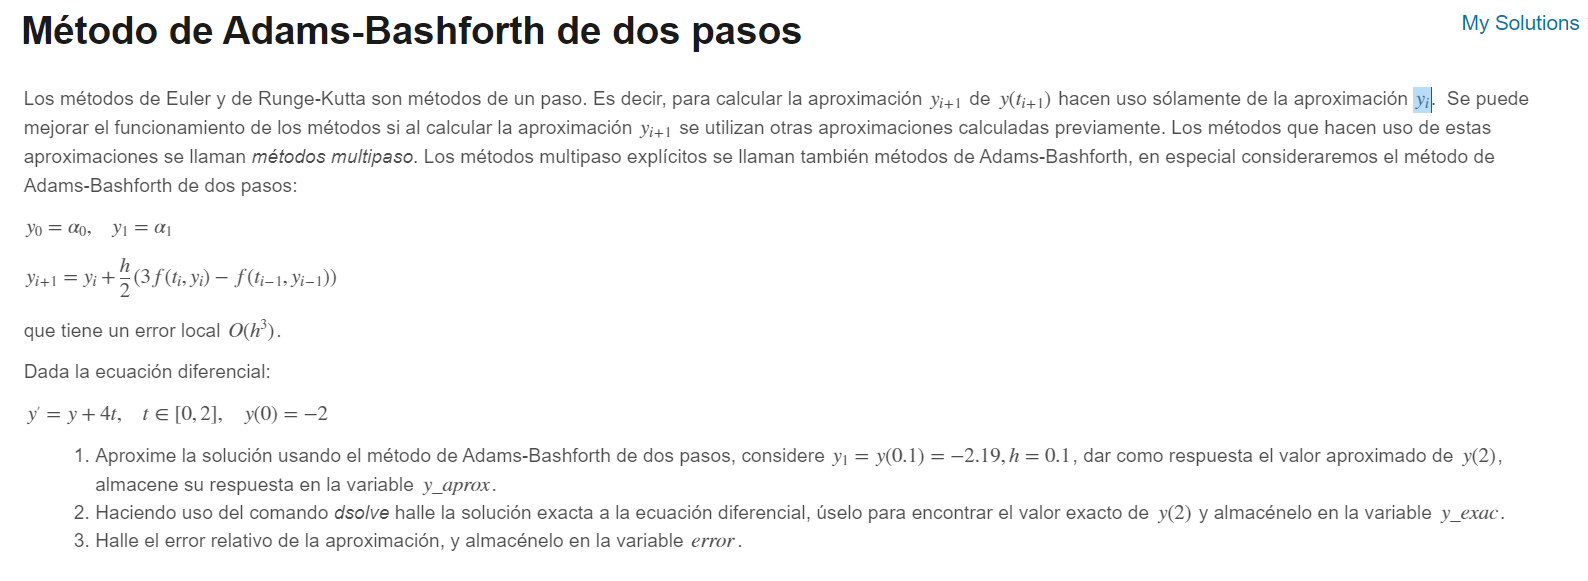

f=@(t,y)(y+4*t);
h=0.1;
tt=0:h:2;
y0=-2;
y1=-2.19;
r=adams_bashforth(f, y0,y1, tt, h);
y_aprox= r(end)

y_aprox =    2.667020062273750


syms y(t) t
y_real1=dsolve(diff(y,t) == y+4*t,y(0)==-2);
y_real1_1=matlabFunction(y_real1);
y_exac=y_real1_1(2)

y_exac =    2.778112197861301


error=abs(y_exac-y_aprox)/abs(y_exac)

error =    0.039988354564324


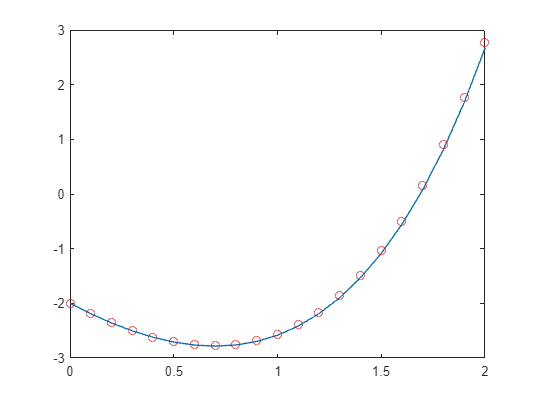

plot(tt',r',tt',y_real1_1(tt),'or')

function y = adams_bashforth(f, y0,y1, t, h)
    y = zeros(size(t));
    y(1) = y0;
    y(2)=y1;
    for i = 2:length(t)-1
        y(i+1)=y(i)+h/2*(3*f(t(i),y(i))-f(t(i-1),y(i-1)));
    end
end